# **Introductory script illustrating how to compute cone mosaic excitation responses to an ISETBio scene generated from a jpeg file.**

*This tutorial generates an ISETBio scene from a jpeg file  as realized on a particular display, passes this scene through the human wavefront-based optics, and computes cone mosaic excitation responses.*

**See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

- t_conePhotocurrentsFromSceneOnDisplay.mlx (photocurrent computation + fixational eye movements)

- `t_treeShrewConeIsomerizationsFromSceneOnDisplay.mlx ` (parameters specific to treeshrew visual system)

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Create a presentation display and realize (on that display) a scene from a JPEG file

We employ an existing display specification, here an Apple LCD display.

%% Create presentation display and place it 57 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);

%% Load the eagle.jpg image and realized it on the presentation display
meanLuminanceCdPerM2 = 40;
fileName = fullfile(isetbioDataPath, 'images', 'rgb', 'eagle.jpg');
realizedStimulusScene = sceneFromFile(fileName, 'rgb', ...
    meanLuminanceCdPerM2, presentationDisplay);

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


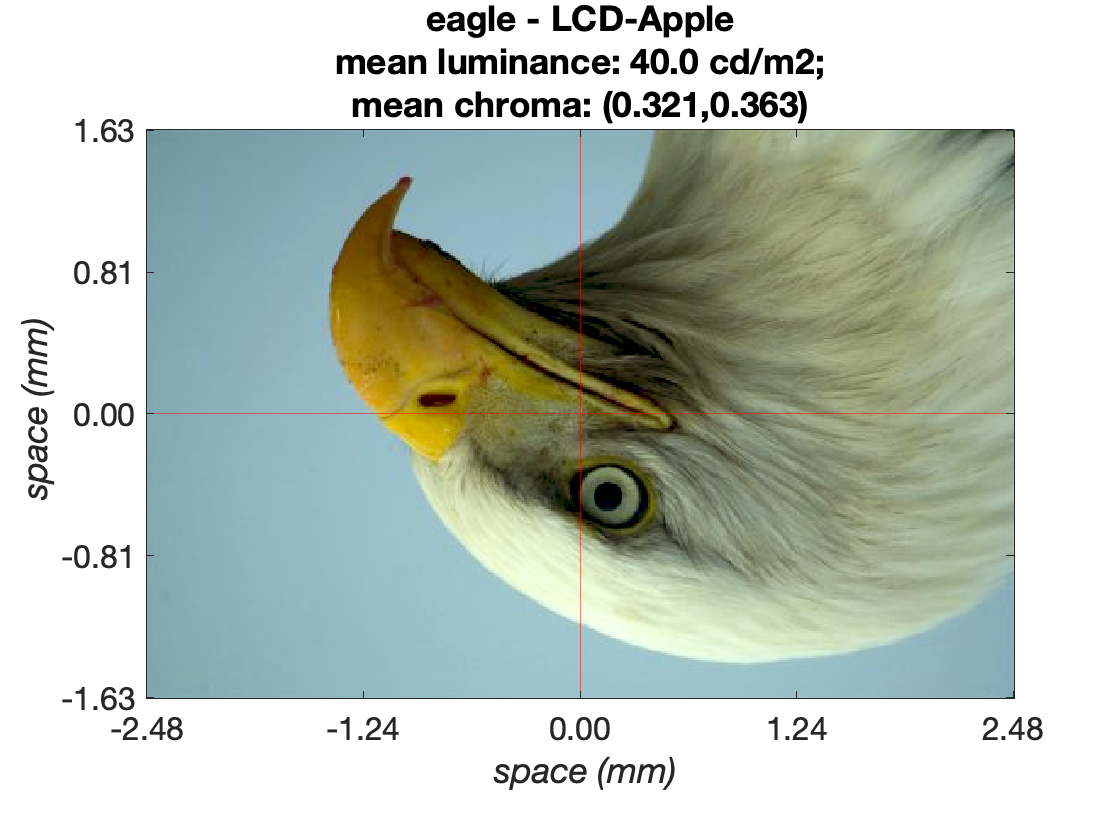

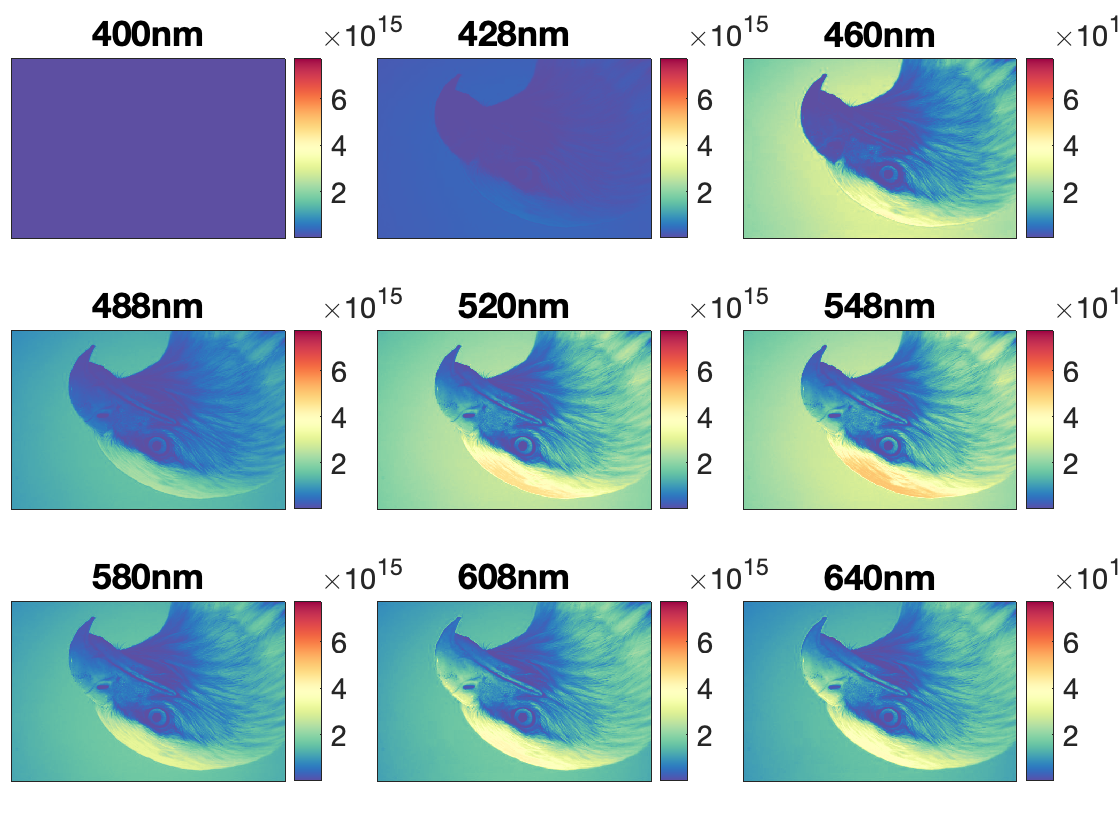


% Set the angular scene width to 0.5 deg
realizedStimulusScene = sceneSet(realizedStimulusScene, 'fov', 0.5);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene);

# **Step 2.** Compute the optical image using wavefront-aberration based optics

We employ the default human optics model which is based on average Zernike coefficiencts from 200 human subjects. The scene is passed through the optics model to compute the retinal image.

### Step 2.1 Generate the default human optics model and visualize the PSF/OTF

%% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');

### Step 2.2 Generate the retinal optical image by passing the scene though the optics

Compute and visualize the retinal 2D image as well as 1D contrast profiles of the retinal image at different wavelengths.

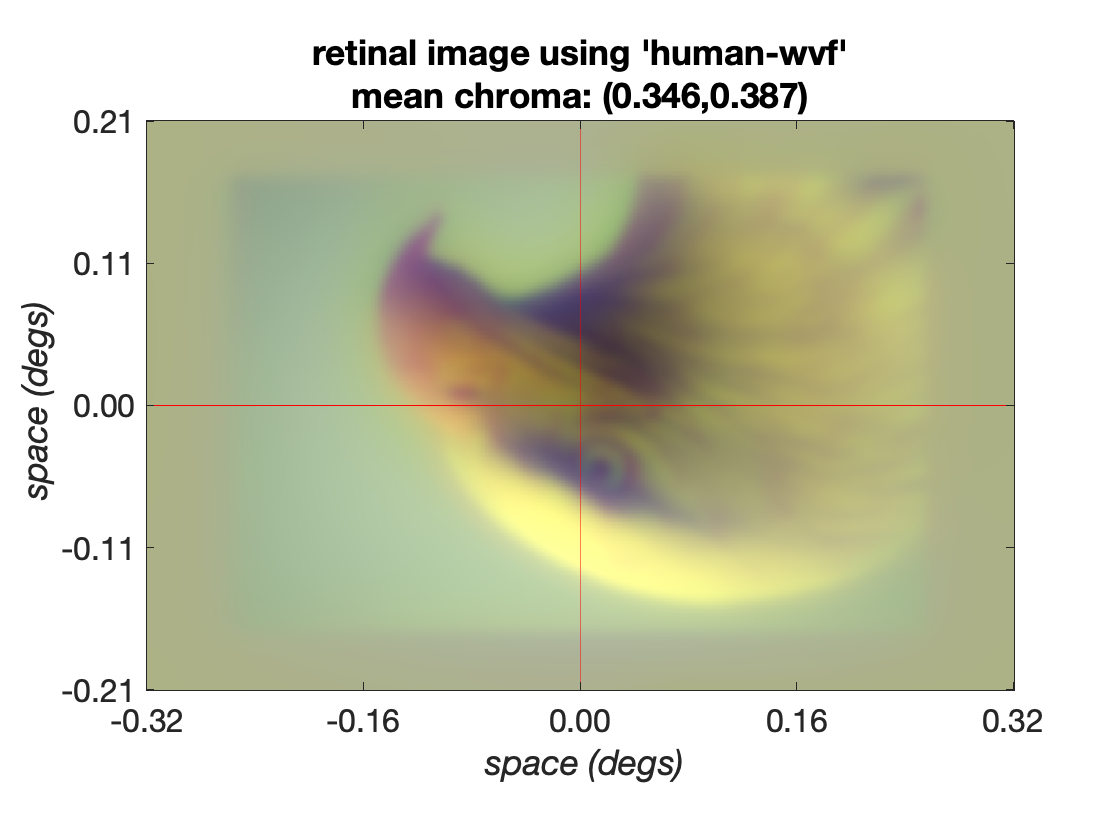

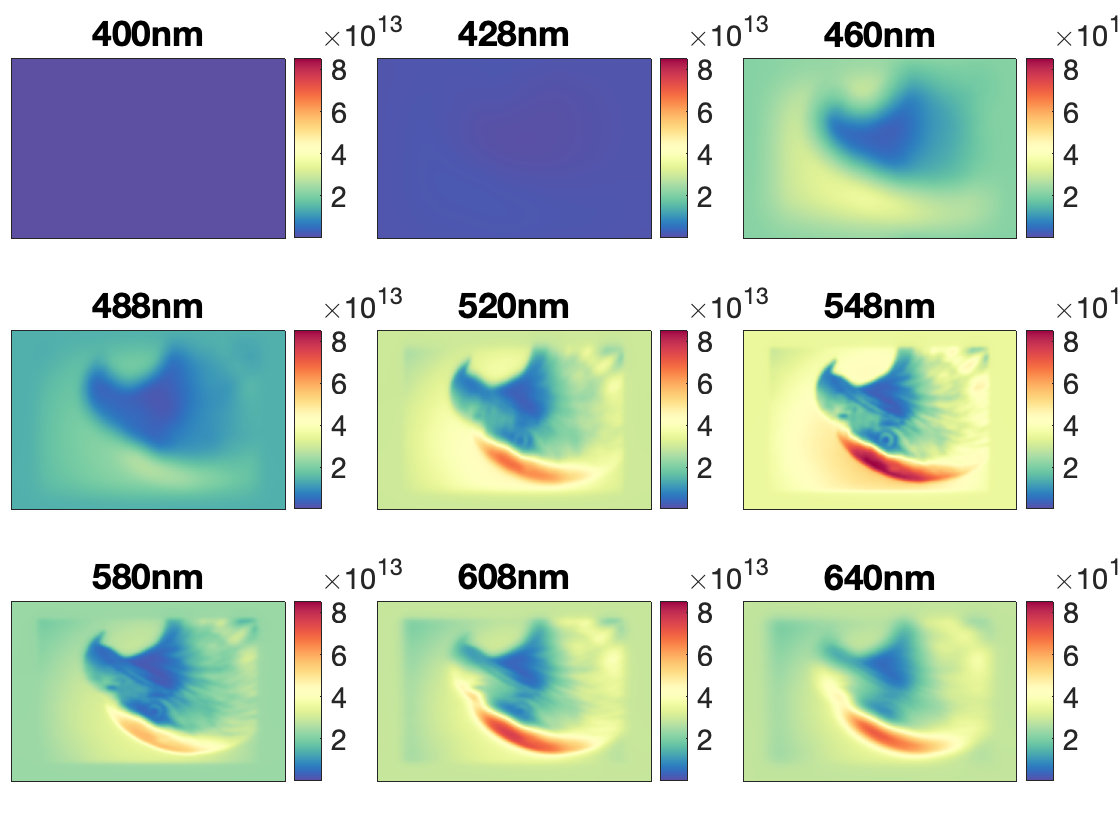

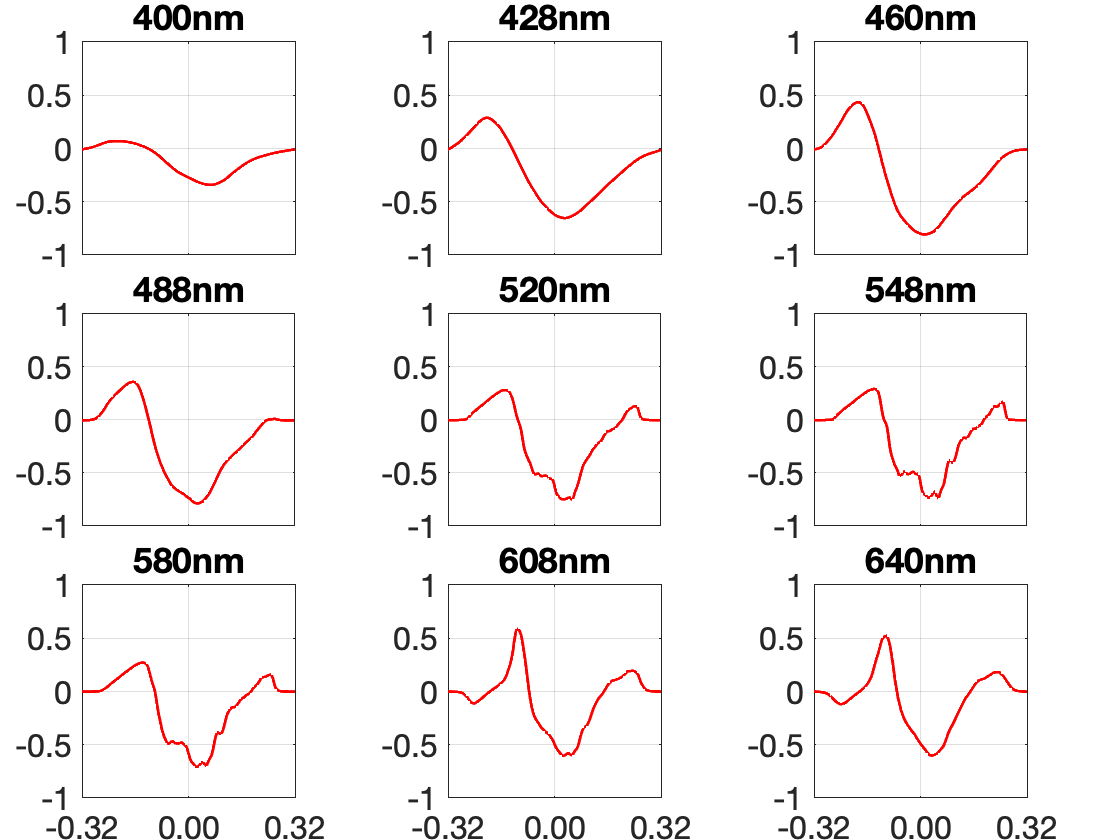

%% Compute the retinal image
theOI = oiCompute(theOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theOI, 'displayRetinalContrastProfiles', true);

Note that the chromaticity of the optical image is different from that of the scene - it is more yellowish. This is due to absorption of short wavelength light by the lens. 

# **Step 3.** Create a cone mosaic object and compute its isomerization response to the optical image for a 20 msec presentation

### Step 3.1 Generate the cone mosaic

We generate a hexagonal, eccentricity-varying cone mosaic, with an integration time of 20 mseconds, and then compute its excitation response to the retinal image generated previously. This step takes some time to compute (~3-5 minutes)

%% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
theMosaic = coneMosaicHex(5, ...              % hex lattice sampling factor
   'fovDegs', sceneGet(realizedStimulusScene,'fov'), ...        % match mosaic width to stimulus size
   'eccBasedConeDensity', true, ...           % cone density varies with eccentricity
   'eccBasedConeQuantalEfficiency', true, ... % cone quantal efficiency varies with eccentricity
   'integrationTime', 5/1000, ...             % 5 msec integration time
   'maxGridAdjustmentIterations', 50);        % terminate iterative lattice adjustment after 50 iterations


Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid adjustment: on iteration 11 ... 
Hex grid adjustment: on iteration 12 ... 
Hex grid adjustment: on iteration 13 ... 
Hex grid adjustment: on iteration 14 ... 
Hex grid adjustment: on iteration 15 ... 
Hex grid adjustment: on iteration 16 ... 
Hex grid adjustment: on iteration 17 ... 
Hex grid adjustment: on iteration 18 ... 
Hex grid adjustment: on iteration 19 ... 
Hex grid adjustment: on iteration 20 ... 
Hex grid adjustment: on iteration 21 ... 
Hex grid adjustment: on iteration 22 ... 
Hex grid adjustment: on iteration 23 ... 
H

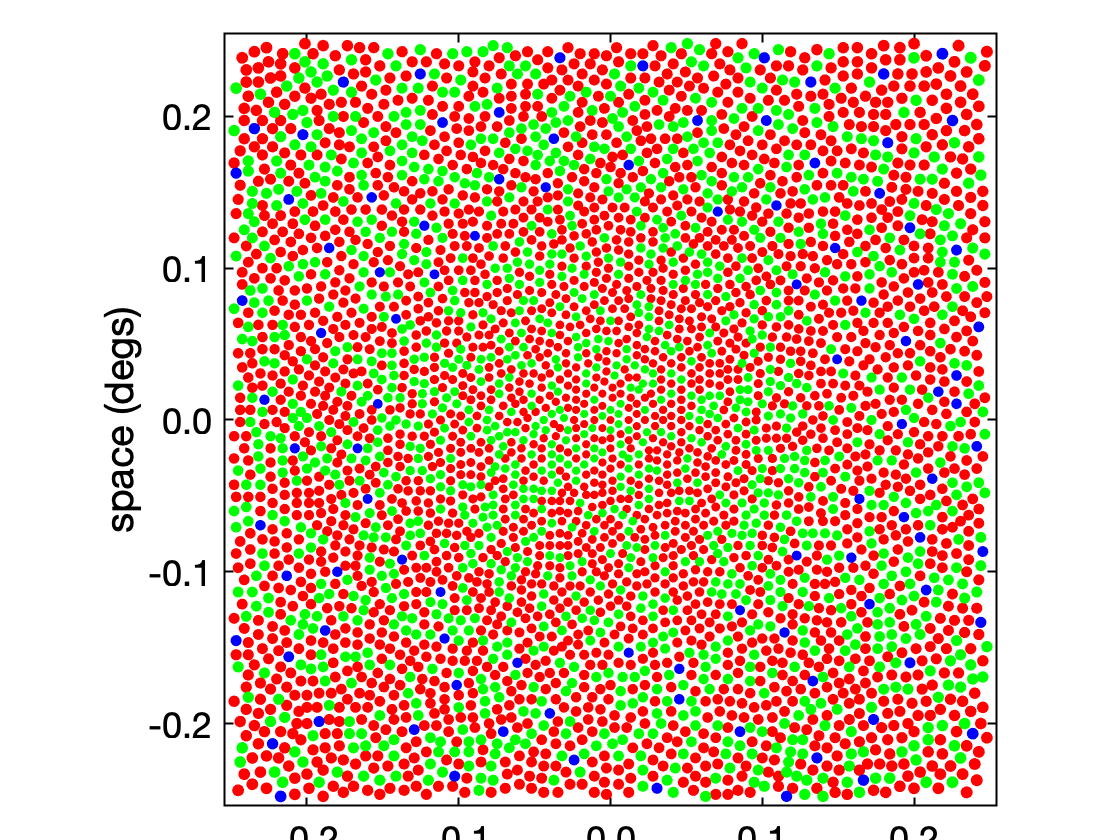

theMosaic.visualizeGrid(...
    'backgroundColor', [1 1 1], ...
    'ticksInVisualDegs', true);

### Step 3.2 Compute mosaic responses to the optical image

Compute 50 responses instances asumming zero fixational eye movements.

% Generate 50 instances of zero movement eye movement paths
nTrialsNum = 50;
emPath = zeros(nTrialsNum, 1, 2);
% Compute mosaic excitation responses
coneExcitations = theMosaic.compute(theOI, 'emPath', emPath);

### Step 3.3 Visualize results. 

We are visualizing the cone mosaic on the left, along with the first two response instances. All computed responses instances for cones located along the horizontal meridian are visualized on the bottom plot.

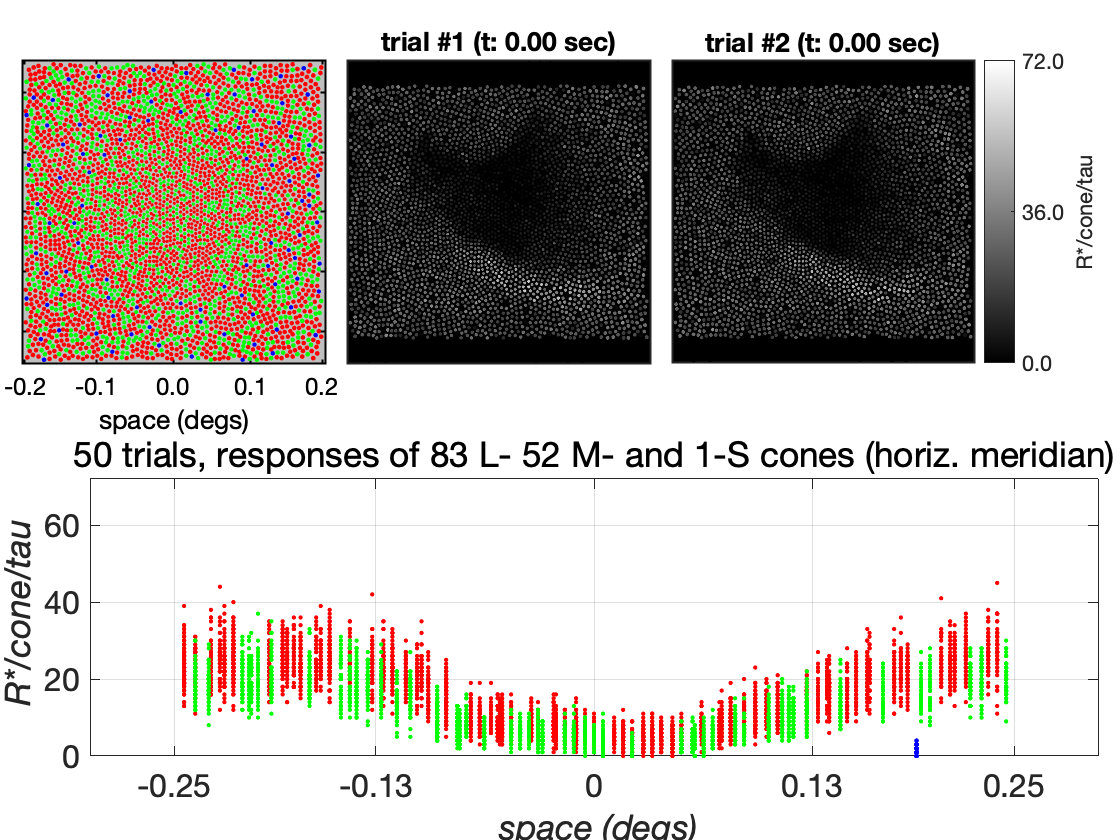

%% Visualize cone mosaic and its cone excitation responses
visualizeConeMosaicResponses(theMosaic, coneExcitations, 'R*/cone/tau');